Loading simulation Model,

simulationModel = "run_q3_feedForward";

Running the experiment

load("system_parameters.mat");
Ts = 0.001;
T_sample = Ts;
load("feed_limited_displacement.mat")
ts = dispProfile(:,1);
xs = dispProfile(:,2);

startTime = 0;
endTime = ts(end);

load("system_parameters.mat");
xd = timeseries(xs,ts);
mkdir("../feedForward");

load("pid_parameters.mat");

Kp = pd_param.Kp;
Ki = pd_param.Ki;
Kd = pd_param.Kd;
ad = exp(-Ts*pd_param.a);

k_acc = m;
k_vel = b;

% -- Run the simulink model programatically

set_param(simulationModel,"StartTime",string(startTime));
set_param(simulationModel,"StopTime",string(endTime));
set_param(simulationModel,"SimulationCommand","start");

pause(endTime + 5);

## For tuning purposes

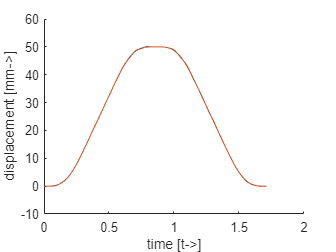

figure();
hold on;
plot(x_sim_in.time,x_sim_in.signals.values);
plot(x_res.time,x_res.signals.values);

xlabel("time [t->]")
ylabel("displacement [mm->]")
hold off;

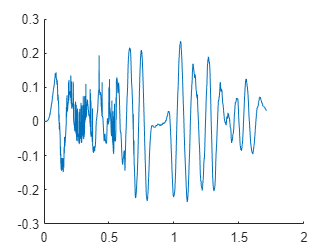


figure();
hold on;
err = x_sim_in.signals.values - x_res.signals.values;
plot(x_sim_in.time,err)

out = struct();
out.x_resp = x_res;
out.xd_in = x_sim_in;
out.u_in = c_in;
out.cont_out = controllerOutput;
out.feedForward_out= feedForwardOutput;

save("Q3_PID_feedforward_experiment_data.mat","out");

## Plotting figures